%Read image

im = imread("/Users/davidbagstevold/Documents/MATLAB/Intro2IA_Mini_Project_complete/Train/captcha_1198.png");
train_folder ="/Users/davidbagstevold/Documents/MATLAB/Intro2IA_Mini_Project_complete/Train";
im_gray = rgb2gray(im);


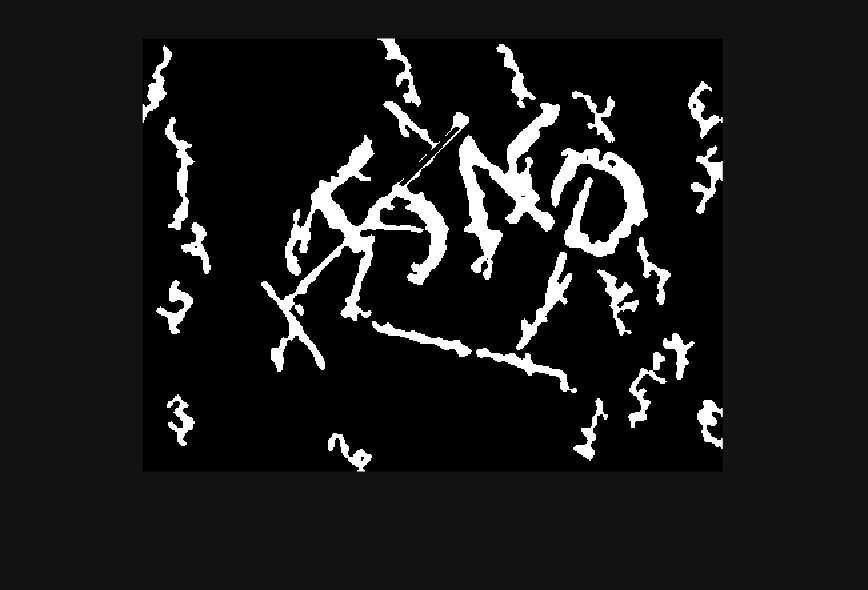

%PREPROCESS
im = imread("/Users/davidbagstevold/Documents/MATLAB/Intro2IA_Mini_Project_complete/Train/captcha_05.png");
im_gray = rgb2gray(im);

img = remove_strips(im);

[s, BW2] = morph(img);
FG = ~BW2;
lineMask = hugh_transform(s, FG);

FG_nolines = FG & ~lineMask;

%FG_nolines = imdilate(FG_nolines, strel('disk', 1));
 
BW_noLines = FG_nolines; 
imshow(BW_noLines)

% train_captcha_positional_svms.m
clear; clc;

imgFolder = "Train/";
labelFile = "Train/labels.txt";
modelOut  = "svm_positional_models.mat";

%% Read labels
fid = fopen(labelFile,'r');
C = textscan(fid,'%s %f %f %f %f','Delimiter',',');
fclose(fid);

ids = strtrim(string(C{1}));
d1  = C{2}; d2 = C{3}; d3 = C{4}; d4 = C{5};
N = numel(ids);

lenY = categorical(3 + ~isnan(d4));   % 3 or 4

%% HOG settings (slightly safer)
imgSize  = [64 192];
cellSize = [8 8];

hogFromROI = @(FGroi) extractHOGFeatures( ...
    uint8(~FGroi)*255, 'CellSize', cellSize);

Xlen = []; X1 = []; X2 = []; X3 = []; X4 = [];
Y1 = categorical(d1); Y2 = categorical(d2);
Y3 = categorical(d3); Y4 = categorical(d4);

%% Feature extraction
for i = 1:N
    fname = fullfile(imgFolder, "captcha_" + ids(i) + ".png");
    im = imread(fname);

    img = remove_strips(im);
    [s, BW2] = morph(img);
    FG = ~BW2;
    lineMask = hugh_transform(s, FG);
    FG = FG & ~lineMask;

    FG = imresize(FG, imgSize, 'nearest');

    fLen = extractHOGFeatures(uint8(~FG)*255, 'CellSize', cellSize);

    [H,W] = size(FG);
    xs = round(linspace(1, W+1, 5));

    f1 = hogFromROI(FG(:,xs(1):xs(2)-1));
    f2 = hogFromROI(FG(:,xs(2):xs(3)-1));
    f3 = hogFromROI(FG(:,xs(3):xs(4)-1));
    f4 = hogFromROI(FG(:,xs(4):xs(5)-1));

    if isempty(Xlen)
        Xlen = zeros(N,numel(fLen),'single');
        X1   = zeros(N,numel(f1),'single');
        X2   = zeros(N,numel(f2),'single');
        X3   = zeros(N,numel(f3),'single');
        X4   = zeros(N,numel(f4),'single');
    end

    Xlen(i,:) = fLen;
    X1(i,:) = f1; X2(i,:) = f2; X3(i,:) = f3; X4(i,:) = f4;
end

%% Split
rng(0);
cv = cvpartition(lenY,'HoldOut',0.2);
tr = training(cv);
te = test(cv);

%% ---- RBF SVM (KEY CHANGE) ----
tRBF = templateSVM( ...
    'KernelFunction','gaussian', ...
    'KernelScale','auto', ...
    'Standardize',true);

LenMdl = fitcecoc(Xlen(tr,:), lenY(tr), 'Learners', tRBF);

M1 = fitcecoc(X1(tr,:), Y1(tr), 'Learners', tRBF);
M2 = fitcecoc(X2(tr,:), Y2(tr), 'Learners', tRBF);
M3 = fitcecoc(X3(tr,:), Y3(tr), 'Learners', tRBF);

idx4 = tr & ~isnan(d4);
M4 = fitcecoc(X4(idx4,:), Y4(idx4), 'Learners', tRBF);

%% ---- Validate correctly ----
predLen = predict(LenMdl, Xlen(te,:));

p1 = predict(M1, X1(te,:));
p2 = predict(M2, X2(te,:));
p3 = predict(M3, X3(te,:));

trueStr = strings(sum(te),1);
predStr = strings(sum(te),1);

teIdx = find(te);
k = 1;
for j = teIdx'
    if predLen(k) == categorical(3)
        predStr(k) = sprintf('%d%d%d', p1(k), p2(k), p3(k));
        trueStr(k) = sprintf('%d%d%d', d1(j), d2(j), d3(j));
    else
        p4 = predict(M4, X4(j,:));   % ONLY when needed
        predStr(k) = sprintf('%d%d%d%d', p1(k), p2(k), p3(k), p4);
        trueStr(k) = sprintf('%d%d%d%d', d1(j), d2(j), d3(j), d4(j));
    end
    k = k + 1;
end

acc = mean(predStr == trueStr);
fprintf("End-to-end validation accuracy: %.2f%%\n", 100*acc);

End-to-end validation accuracy: 0.00%



save(modelOut,"LenMdl","M1","M2","M3","M4","imgSize","cellSize");
